% A few new analysis

saveDataPath = 'C:\Users\chenz\Work\zhec\WE43_T6_C1\Analysis_2021_09';
  

## **-- Do large grains twin first?  Maybe a little bit**

 info needed: iE, ID, gDiameter, iTwin, tSF, iE_twin

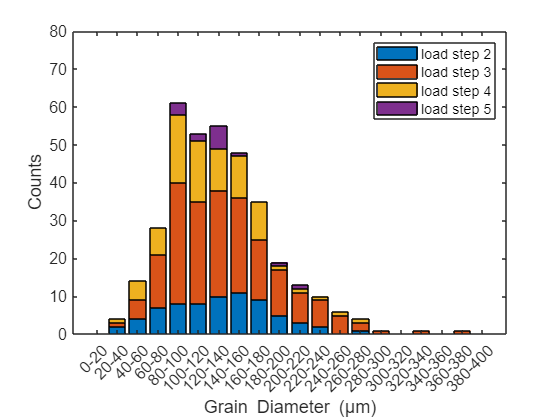

iE = 5; % This will include twins activated at all iEs
load(fullfile(saveDataPath, ['twin_gb_summary_',num2str(iE),'.mat']), 'T', 'T2', 'struCell');
TT = [T;T2];  % T is for grains with active twins, T2 is for grains without active twins

ID_twinned = unique(T.ID);
ID_unique = unique(TT.ID);

% analysis to find out at which iE does each grain twinned:
% at iE = 5
% for each ID_current
%     if ismember(ID_current, T.ID)    % this grain is twinned
%         find out at which iE it first twinned

df = [];
for ii = 1:length(ID_unique)
    ID_current = ID_unique(ii);
    inds =  ismember(T.ID, ID_current);
    if sum(inds) > 0
        t = T(inds,:);
        [iiE,ind] = min(t.iiE_each_twin);
        df = [df; ID_current, t.gDia(ind), t.iiE_each_twin(ind)];
    end
end


% plot
edges = [0:20:400];
x_label = [];
for ii = 1:length(edges)-1
    x_label{ii} = [num2str(edges(ii)),'-',num2str(edges(ii+1))];
end
cats = unique(df(:,3)); % category = iiE = [2,3,4,5]
N_total = [];

for ii = 1:length(cats)
    cat_current = cats(ii);
    df_cat = df(df(:,3)==cat_current,2);
    N_total = [N_total, histcounts(df_cat,edges)'];
end
figure;
bar(N_total,'stacked');
legend({'load step 2','load step 3','load step 4','load step 5'},'location','northeast');
set(gca,'xTick',1:length(x_label),'xTickLabel',x_label,'ylim',[0,80],'fontsize',12);
xlabel('Grain Diameter (\mum)');
ylabel('Counts');

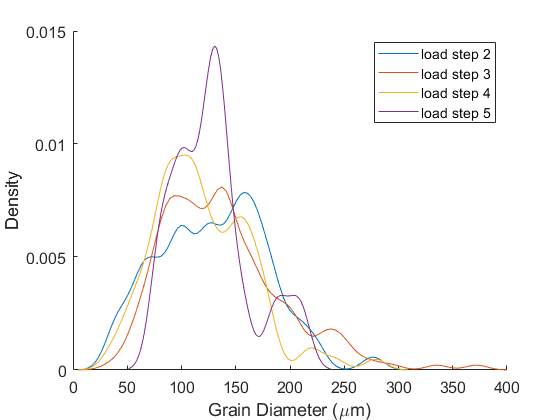



% kernal smooth density function
% Compare peak position of curves of different iEs, 
figure; hold on;
for ii = 1:length(cats)
    cat_current = cats(ii);
    df_cat = df(df(:,3)==cat_current,2);
    [f,xi] = ksdensity(df_cat,'Bandwidth',10);
    plot(xi,f);
end
set(gca,'fontsize',12,'xlim',[0 400]);
legend({'load step 2','load step 3','load step 4','load step 5'},'location','northeast');
xlabel('Grain Diameter (\mum)');
ylabel('Density');

**Summarize grain size distribution**

% get row indices to extract info. Each grain only analyze once
iRow = 1;
nRow = size(TT,1);
current_id = nan;
indR = false(nRow,1);
while iRow <= nRow
    if current_id ~= TT.ID(iRow)
        current_id = TT.ID(iRow);
        indR(iRow) = 1;
    end
    iRow = iRow + 1;
end
t = TT(indR,:);
quantile(t.gDia, [0.005, 0.025, 0.05, 0.95, 0.975, 0.995])

ans =     1.7879   29.6794   39.8551  215.4806  240.9258  289.8695


## **The effect of misorientation is minimum (look at iE=5)**

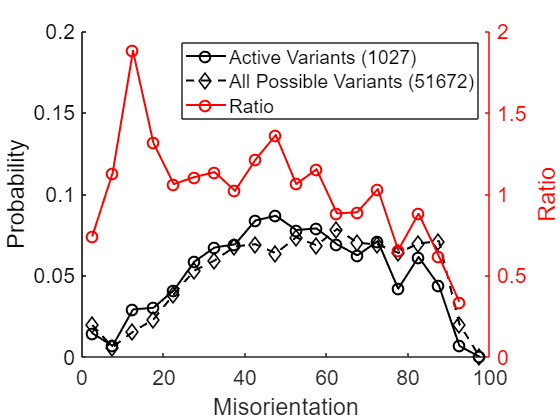

iE = 5;
load(fullfile(saveDataPath, ['twin_gb_summary_',num2str(iE),'.mat']), 'T', 'T2', 'struCell');
TT = [T;T2];  % T is for grains with active twins, T2 is for grains without active twins

edges = 0:5:100;
xpos = edges(1:end-1) + 2.5;

% look at all active variants
ind = (T.iiE_each_twin_at_this_boundary == T.iiE_each_twin)&(T.iiE_each_twin<=iE);
t = T(ind,:);
N = histcounts(t.miso, edges);
% all possible variants
N2 = histcounts(TT.miso, edges); 

pmf_all_exp = N./sum(N);
pmf_all = N2./sum(N2);

figure; disableDefaultInteractivity(gca); hold on;
plot(xpos, pmf_all_exp, '-ko','linewidth',1.5,'MarkerSize',8);
plot(xpos, pmf_all, '--kd','linewidth',1.5,'MarkerSize',8);
set(gca,'ylim',[0 0.2]);
ylabel('Probability');
yyaxis right;
plot(xpos, pmf_all_exp./pmf_all, '-ro','linewidth',1.5,'MarkerSize',8);
set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1]);
ylabel('Ratio');
xlabel('Misorientation');
set(gca,'fontsize',16);
legend({['Active Variants (',num2str(sum(N)),')'], ['All Possible Variants (',num2str(sum(N2)),')'], 'Ratio'},'location','northeast');
title('');

## **Is at least one variant of the high-SF variant pair active?**

Needed: iE, ID_current, iTwin, tSF, tActive

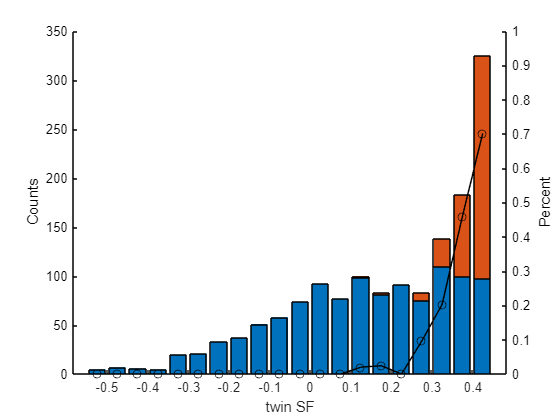

iE = 5; % target iE to analyze
load(fullfile(saveDataPath, 'WE43_T6_C1_tableSummary_twinStats_selfEffect.mat'),'T','T2');

% Analysis algorithm:
% Needed: iE, ID_current, iTwin, tSF, tActive
% for selected iE
%   for each grain
%     find iTwin where twin system iTwin has max twin SF
%     find if either twin system iTwin or rem(iTwin+3,6) is active

edges = -0.5:0.05:0.5;
xpos = edges(1:end-1)-0.025;
ID_unique = unique(T2.ID);
df = [];
for ii = 1:length(ID_unique)
    ID_current = ID_unique(ii);
    inds =  ismember(T2.ID, ID_current) & (T2.iE >= iE);
    if sum(inds) > 0
        t = T2(inds,:);
        [tSF,ind] = max(t.variant_SF);
        ok = t.vActiveTF(ind) | t.vActiveTF(rem(ind+2,6)+1);
        df = [df; iE, ID_current, tSF, ok];
    end
end

t1 = df(df(:,4)>0,3);
t2 = df(df(:,4)==0,3);
N_twin = histcounts(t1,edges);
N_notwin = histcounts(t2,edges);

figure; hold on;
bar(xpos, [N_notwin',N_twin'],'stacked');
ylabel('Counts');
yyaxis right;
plot(xpos, N_twin./(N_twin+N_notwin), '-ok');
set(gca,'ycolor','k','ylim',[0 1]);
xlabel('twin SF');
ylabel('Percent');

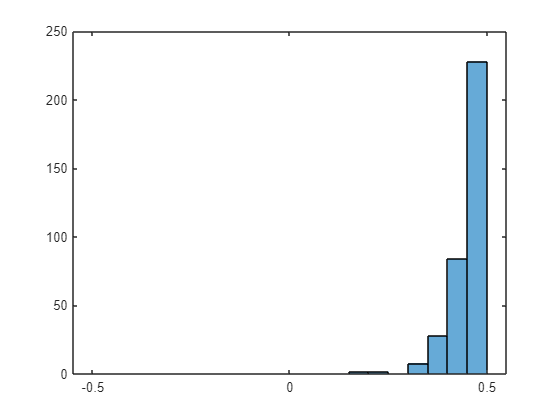


figure;
histogram(df(df(:,4)>0,3),edges);

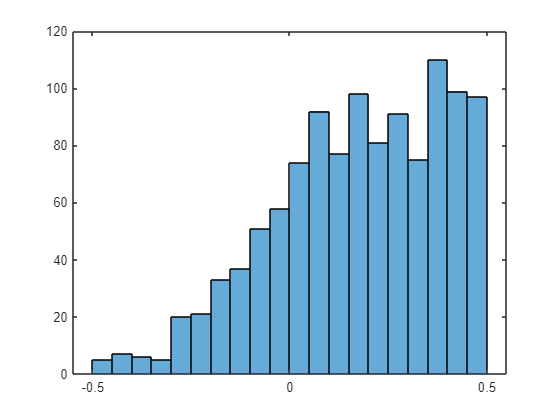

figure;
histogram(df(df(:,4)==0,3),edges);